## cse327 hw5

Zian Shang

####     Notes:   

-  Change the image in the 2nd code box between Idesk and Idesk2

-  The first point clicked is the seed point, marked in red circle; the 2nd point is the goal point, marked in green circle

-  It might take some time for the code to run

####     Problems: 

- The line is some times distracted by other boundaries intersecting it, better to choose areas with a plain background and large intensity change on either side of the line

- The x and y boundaries for valid q points is currently set to >0 && <=ncols instead of x<=nrows and y<=ncols since it would return error if x is set to <=nrows saying boundaries should be smaller than ncols (191 in Idesk)

% read both images & display figure 
[Idesk, map1] = imread("desk.jpg");
[Idesk2, map2] = imread("desk2.jpg");

Idesk = double(Idesk);
Idesk2 = double(Idesk2);

 Set or change the target image here.

I = Idesk;

Set up some variables.

[nrows, ncols] = size(I);        % Get image dimensions
cost = inf(nrows, ncols);        % Create a cost matrix, setting each value = infinity
activeList = [];                 % activeList
bExpanded = ones(nrows, ncols);  % non-expanded points = 1, if expanded, set 0

% parent_matrix, cell{i, j} contains the parent of this point if it has one, otherwise {0,0}
parent_matrix = cell([nrows, ncols]);
for i = 1 : nrows
    for j = 1:ncols
        parent_matrix{i, j}  ={0, 0};
    end
end

Now, display the image and let the user choose two points as seed and goal.

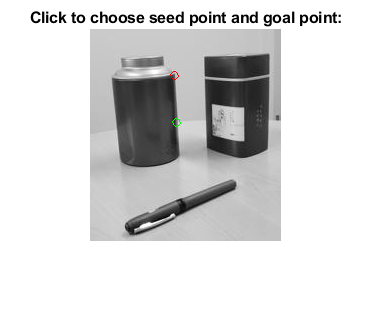

imshow(uint8(I));
title("Click to choose seed point and goal point:");

[Xseed, Yseed] = ginput(1);
hold on;
plot(Xseed, Yseed, "ro", "MarkerSize",5); % mark Pseed with a red circle

[Xgoal, Ygoal] = ginput(1);
plot(Xgoal, Ygoal, "go", "MarkerSize",5); % mark Pgoal with a green circle
hold off;

% get Pseed and Pgoal in matrix order
Pseed = [Yseed, Xseed];
Pgoal = [Ygoal, Xgoal];           

cost(round(Yseed), round(Xseed)) = 0;% Set cost at Pseed = 0
activeList{end+1} = {Yseed, Xseed};  % Insert Pseed into the active list, matrix order

Start looping below.

while(~isempty(activeList))
    flag = true; % Flag to break the loop when Pgoal is found

    p = find_p(activeList, cost); % Find p coordinate from activeList with the smallest cost
    px = p{1};
    py = p{2};
    p_coordinate = [px, py];
    p_cost = cost(round(px), round(py));
    for u = -1:1
        for v = -1:1
            qx = px+u;            % Find q point
            qy = py+v;
            q = [qx,qy];

            % **If neighbor q is out of the boundary, jump to the next**
            if(qx<1 || qx>ncols || qy<1 || qy>ncols)
                continue
            end

            % bExpanded stores the point used as 0, and unused points as 1
            if(bExpanded(round(qx), round(qy))==1 && ~isequal(p_coordinate,q))           
                q_cost = cost(round(qx),round(qy));

                % **Get the new cost to q**
                cost(round(qx),round(qy)) = min(p_cost+pq_getCost(I, p_coordinate, q), q_cost);
                new_cost = cost(round(qx),round(qy));
                % if cost(q) changes, then parent(q) = p
                if(new_cost ~= q_cost)
                    parent_matrix{ round(qx), round(qy) } = {px, py};
                end

                % Insert q into the activeList** use function
                activeList = active_insert(activeList, q);
                
                % Break out of inner for loop if q is Pgoal
                if(qx == Pgoal(1) && qy == Pgoal(2))
                   flag = false;
                   break;
                end

            end
        end 
        % break the outer for loop if q is Pgoal
        if (~flag)
            break;
        end

    end
    % Remove P from activeList
    activeList = removeFromList(activeList, p);
    % Set bExpanded(p) = true
    bExpanded(round(px), round(py)) = 0;

    % break the while loop if q is Pgoal
    if (~flag)
        break;
    end

end

In the end, extract the list of points from the parent matrix and plot them onto the graph. 

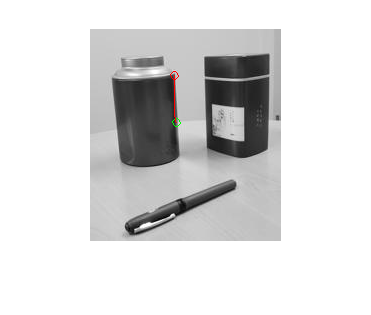

pathList = [];
% store Pgoal into the pathList as the 1st point, matrix order
pathList{end+1} = {Ygoal, Xgoal};

% get the first parent coordinate
parent = parent_matrix{round(Ygoal), round(Xgoal)};
tmpX = parent{1};
tmpY = parent{2};

while(tmpX~=0 || tmpY~=0)
    % Insert the previous parent into the list
    pathList{end+1} = {tmpX, tmpY};
    % Calculate next parent
    parent = parent_matrix{round(tmpX), round(tmpY)};
    tmpX = parent{1};
    tmpY = parent{2};
end

listY = cellfun(@(p) p{1}, pathList);  % Extract x coordinates
listX = cellfun(@(p) p{2}, pathList);  % Extract y coordinates

% plot all parent points to the image
imshow(uint8(I));

hold on;

plot(Xseed, Yseed, "ro", "MarkerSize",5); % mark Pseed with a red circle
plot(Xgoal, Ygoal, "go", "MarkerSize",5); % mark Pgoal with a green circle

% Plot the points using scatter or plot
scatter(listX, listY, 1, 'r', 'filled');

% Use the plot function to connect the points with lines
plot(listX, listY,'r');

hold off;

Implement other helper functions below.

% function to find lowest cost p from the activeList

function p = find_p(activeList, cost)
    p = activeList{1};
    p_cost = cost(round(p{1}), round(p{2}));

    for i = 1: length(activeList)
        tmp = activeList{i};
        tmp_cost = cost( round(tmp{1}), round(tmp{2}) );
        if (tmp_cost < p_cost)
            p_cost = tmp_cost;
            p = tmp;
        end
    end
end

% function to remove p from activeList
function updatedList = removeFromList(activeList, p)
    % Initialize a new cell array to store the filtered values
    updatedList = cell(1, 0);
    
    % Iterate through the original cell array and exclude the point to be removed
    for i = 1:numel(activeList)
        % Check if the current cell contains the point to be removed
        if ~isequal(activeList{i}, p)
            % Add the cell to the updated cell array
            updatedList{end+1} = activeList{i};
        end
    end

end

% function to calculate cost between p and q
function Cpq = pq_getCost(Image, p, q)
    % Normalize weight with max intensity values in Image
    maxI = max(Image(:));

    % Define a distance matrix in the 3x3 neighborhood
    d = [sqrt(2) 1 sqrt(2);
               1 0 1;
         sqrt(2) 1 sqrt(2)];

    % Calculate the relative position of q wrt p, matrix order
    qx = round( 2 + (q(1) - p(1)) );
    qy = round( 2 + (q(2) - p(2)) );
    
    % Calculate the cost between pq
    Cpq = ( maxI - abs( Image( round(q(2)), round(q(1)) ) ) ) * d(qx, qy) ;
end

% function to insert q point into the activeLit in each round if q is not active
function activeList = active_insert(activeList, q)
    qx = q(1);
    qy = q(2);
    flag = true;

    % Loop through the activeList and check if q is already inside
    for i  = 1: numel(activeList)
        % if q exists, set flag false, do not update activeList
        if(isequal(activeList{i}{1}, qx) && isequal(activeList{i}{2}, qy))
            flag = false;
        end
    end
    
    % if flag still true, update activeList, insert q
    if(flag)
        activeList{end+1} = {qx, qy};
    end
end